## Analysis Pipeline for PEP WP-4 fMRI Project

### House keeping

clc; clear; close all;%dbstop if error;
cfg = struct;
d = struct;

% add functions folder to path
cfg.functionPath = fullfile(pwd,'utilities');
addpath(genpath(cfg.functionPath))


### Define to-be-analyzed subjects

cfg.subNums = [101:117, 119:124]; % 118 did not finish the experiment
cfg = defaultCfg(cfg);


### Preprocessing

disp(['Running pre-processing...' newline]);

Running pre-processing...



preproc_func(cfg);

Preprocessed data for subject 101 exists already
Preprocessed data for subject 102 exists already
Preprocessed data for subject 103 exists already
Preprocessed data for subject 104 exists already
Preprocessed data for subject 105 exists already
Preprocessed data for subject 106 exists already
Preprocessed data for subject 107 exists already
Preprocessed data for subject 108 exists already
Preprocessed data for subject 109 exists already
Preprocessed data for subject 110 exists already
Preprocessed data for subject 111 exists already
Preprocessed data for subject 112 exists already
Preprocessed data for subject 113 exists already
Preprocessed data for subject 114 exists already
Preprocessed data for subject 115 exists already
Preprocessed data for subject 116 exists already
Preprocessed data for subject 117 exists already
Preprocessed data for subject 119 exists already
Preprocessed data for subject 120 exists already
Preprocessed data for subject 121 exists already
Preprocessed data fo

### **First level GLM (using GLM single toolbox)**

disp(['Running first level GLM...' newline]);

Running first level GLM...



GLMsingle_new_script(cfg)

Data for subject 101 exists already
Data for subject 102 exists already
Data for subject 103 exists already
Data for subject 104 exists already
Data for subject 105 exists already
Data for subject 106 exists already
Data for subject 107 exists already
Data for subject 108 exists already
Data for subject 109 exists already
Data for subject 110 exists already
Data for subject 111 exists already
Data for subject 112 exists already
Data for subject 113 exists already
Data for subject 114 exists already
Data for subject 115 exists already
Data for subject 116 exists already
Data for subject 117 exists already
Data for subject 119 exists already
Data for subject 120 exists already
Data for subject 121 exists already
Data for subject 122 exists already
Data for subject 123 exists already
Data for subject 124 exists already


### Define functional ROIs using localizer

disp(['Get functional ROIs...' newline]);

Get functional ROIs...



level1_glm_norm_func(cfg)

Starting first level glm in SPM for subject 101
Data for subject 101 exists already
Starting first level glm in SPM for subject 102
Data for subject 102 exists already
Starting first level glm in SPM for subject 103
Data for subject 103 exists already
Starting first level glm in SPM for subject 104
Data for subject 104 exists already
Starting first level glm in SPM for subject 105
Data for subject 105 exists already
Starting first level glm in SPM for subject 106
Data for subject 106 exists already
Starting first level glm in SPM for subject 107
Data for subject 107 exists already
Starting first level glm in SPM for subject 108
Data for subject 108 exists already
Starting first level glm in SPM for subject 109
Data for subject 109 exists already
Starting first level glm in SPM for subject 110
Data for subject 110 exists already
Starting first level glm in SPM for subject 111
Data for subject 111 exists already
Starting first level glm in SPM for subject 112
Data for subject 112 exists 


cfg.func_roi_names = {'PPA', 'TOS', 'RSC', 'LOC', 'LPFC'};
funcROIs(cfg)

    Saved functional ROI for PPA to C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gießen\Dokumente\GitHub\pep_wp4_fMRI\code\..\MNI_ROIs\func_ROIs\sub-101\PPA_funcROI.nii
    Saved functional ROI for TOS to C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gießen\Dokumente\GitHub\pep_wp4_fMRI\code\..\MNI_ROIs\func_ROIs\sub-101\TOS_funcROI.nii
    Saved functional ROI for RSC to C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gießen\Dokumente\GitHub\pep_wp4_fMRI\code\..\MNI_ROIs\func_ROIs\sub-101\RSC_funcROI.nii
    Saved functional ROI for LOC to C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gießen\Dokumente\GitHub\pep_wp4_fMRI\code\..\MNI_ROIs\func_ROIs\sub-101\LOC_funcROI.nii
    Saved functional ROI for LPFC to C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gießen\Dokumente\GitHub\pep_wp4_fMRI\code\..\MNI_ROIs\func_ROIs\sub-101\LPFC_funcROI.nii
    Saved functional ROI for PPA to C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gießen\Dokumente\GitHub\

### RDM of pairwise decoding on beta maps (seperate for each subject)

disp(['Running pairwise decoding...' newline]);

Running pairwise decoding...



cfg.plotting = false;
cfg.rois = {'wV1.nii', 'wV2.nii', 'wLOC.nii',...
    'wPPA.nii', 'wTOS.nii', 'wRSC.nii', 'wLPFC.nii'...
    'wmotorCortex.nii', 'wS1.nii', 'wauditoryCortex.nii'};
[d.pairRep, cfg] = PairwiseROIsLDAclassifier(cfg);

Starting pairwise ROI decoding for subject 101 on b-map
RDM for wV1 already exists
RDM for wV2 already exists
RDM for wLOC already exists
RDM for wPPA already exists
RDM for wTOS already exists
RDM for wRSC already exists
RDM for wLPFC already exists
RDM for wmotorCortex already exists
RDM for wS1 already exists
RDM for wauditoryCortex already exists
Starting pairwise ROI decoding for subject 102 on b-map
RDM for wV1 already exists
RDM for wV2 already exists
RDM for wLOC already exists
RDM for wPPA already exists
RDM for wTOS already exists
RDM for wRSC already exists
RDM for wLPFC already exists
RDM for wmotorCortex already exists
RDM for wS1 already exists
RDM for wauditoryCortex already exists
Starting pairwise ROI decoding for subject 103 on b-map
RDM for wV1 already exists
RDM for wV2 already exists
RDM for wLOC already exists
RDM for wPPA already exists
RDM for wTOS already exists
RDM for wRSC already exists
RDM for wLPFC already exists
RDM for wmotorCortex already exists
RDM for

### RDM of correlation of mean betas (seperate for each subject)

disp(['Running pairwise correlations...' newline]);

Running pairwise correlations...



Starting simple RDM for subject 101 on b-map
RDM for wV1 already exists
RDM for wV2 already exists
RDM for wLOC already exists
RDM for wPPA already exists
RDM for wTOS already exists
RDM for wRSC already exists
RDM for wLPFC already exists
RDM for wmotorCortex already exists
RDM for wS1 already exists
RDM for wauditoryCortex already exists
Starting simple RDM for subject 102 on b-map
RDM for wV1 already exists
RDM for wV2 already exists
RDM for wLOC already exists
RDM for wPPA already exists
RDM for wTOS already exists
RDM for wRSC already exists
RDM for wLPFC already exists
RDM for wmotorCortex already exists
RDM for wS1 already exists
RDM for wauditoryCortex already exists
Starting simple RDM for subject 103 on b-map
RDM for wV1 already exists
RDM for wV2 already exists
RDM for wLOC already exists
RDM for wPPA already exists
RDM for wTOS already exists
RDM for wRSC already exists
RDM for wLPFC already exists
RDM for wmotorCortex already exists
RDM for wS1 already exists
RDM for waudi

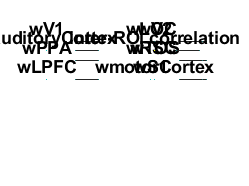

cfg.plotting = true;
d.corrRep = SimpleRDM(cfg);

### Get inter-subject similarity on drawings

cfg.regressOutMean = true;
cfg.dissimilarity = true;
cfg.ISC_types = {'pairRep', 'corrRep'};
cfg.correlation_type = 'spearman';
cfg.plotting = false;
cfg.new_figure = false;
d = getISCofRespresentation(cfg, d);

Unrecognized field name "pairRep".

Error in getISCofRespresentation (line 30)
                rdm = squeeze(d.(cfg.ISC_type).(subID2).(mask_label_short).rdm);

### Get inter-subject similarity on drawings

cfg.dnn = 'vgg16_imagenet';
cfg.layer_type = 'late';
cfg.correlation_type = 'Spearman';
cfg.dissimilarity = true;

% Create output directory if wanted
output_dir = fullfile(pwd, '..', 'dnn_features');
if exist(output_dir, 'dir')
    rmdir(output_dir, 's');
end

% get images
cfg.analysis_names = {'typical', 'control','photos'};
images = load_images(cfg);

Loaded image: 101_bat_gen1.png
Loaded image: 101_bat_gen2.png
Loaded image: 101_bat_gen3.png
Loaded image: 102_bat_gen1.png
Loaded image: 102_bat_gen2.png
Loaded image: 102_bat_gen3.png
Loaded image: 103_bat_gen1.png
Loaded image: 103_bat_gen2.png
Loaded image: 103_bat_gen3.png
Loaded image: 104_bat_gen1.png
Loaded image: 104_bat_gen2.png
Loaded image: 104_bat_gen3.png
Loaded image: 105_bat_gen1.png
Loaded image: 105_bat_gen2.png
Loaded image: 105_bat_gen3.png
Loaded image: 106_bat_gen1.png
Loaded image: 106_bat_gen2.png
Loaded image: 106_bat_gen3.png
Loaded image: 107_bat_gen1.png
Loaded image: 107_bat_gen2.png
Loaded image: 107_bat_gen3.png
Loaded image: 108_bat_gen1.png
Loaded image: 108_bat_gen2.png
Loaded image: 108_bat_gen3.png
Loaded image: 109_bat_gen1.png
Loaded image: 109_bat_gen2.png
Loaded image: 109_bat_gen3.png
Loaded image: 110_bat_gen1.png
Loaded image: 110_bat_gen2.png
Loaded image: 110_bat_gen3.png
Loaded image: 111_bat_gen1.png
Loaded image: 111_bat_gen2.png
Loaded i


% typical images
cfg.analysis_name = 'typical';
[d, cfg] = get_dnn_layer_similarity(d, images, cfg);

analysis typical - layer #1 - category: bathroom
analysis typical - layer #1 - category: kitchen



% control images
cfg.analysis_name = 'control';
[d, cfg] = get_dnn_layer_similarity(d, images, cfg);

analysis control - layer #1 - category: bathroom
analysis control - layer #1 - category: kitchen



% photos
cfg.analysis_name = 'photos';
[d, cfg] = get_dnn_layer_similarity(d, images, cfg);

analysis photos - layer #1 - category: bathroom
analysis photos - layer #1 - category: kitchen



% filter for included subjects
d = filterCurrentSubs(d, cfg)

d = struct with fields:
                         DNN: [1×1 struct]
                bathroom_RDM: [1×1 struct]
                 kitchen_RDM: [1×1 struct]
                splitHalfISC: [1×1 struct]
    compare_roi_to_predictor: [1×1 struct]


### Compare ISC from drawings with ISC of neural representations 

 Start evaluating predictor RDMs
Predictor RDMs evaluated
10% of permutations of V1 bathroom is done
20% of permutations of V1 bathroom is done
30% of permutations of V1 bathroom is done
40% of permutations of V1 bathroom is done
50% of permutations of V1 bathroom is done
60% of permutations of V1 bathroom is done
70% of permutations of V1 bathroom is done
80% of permutations of V1 bathroom is done
90% of permutations of V1 bathroom is done
100% of permutations of V1 bathroom is done
Compare inter-subject RDM of V1 with partial correaltion of predictor RDMs - bathroom
 Start evaluating predictor RDMs
Predictor RDMs evaluated
10% of permutations of V1 kitchen is done
20% of permutations of V1 kitchen is done
30% of permutations of V1 kitchen is done
40% of permutations of V1 kitchen is done
50% of permutations of V1 kitchen is done
60% of permutations of V1 kitchen is done
70% of permutations of V1 kitchen is done
80% of permutations of V1 kitchen is done
90% of permutations of V1 kitch

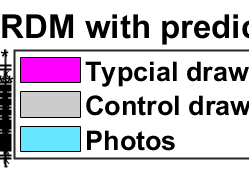

% preparation
cfg.partial_cor = true;
cfg.plotting = true;
cfg.plot_rdm = false;
cfg.predictor_RDMs = {'typical_late', 'control_late', 'photos_late'};
cfg.RDM_to_partial_out = cfg.predictor_RDMs;
cfg.rois_of_interest = {'V1', 'V2', ...
    'LOC', 'PPA', 'TOS', 'RSC', 'LPFC', ...
    'motorCortex', 'S1', 'auditoryCortex'};
cfg.dnns = {'vgg16_imagenet'};
cfg.plot_type = 'bar';
cfg.show_single_cate = true;
cfg.permutation_test = true;
cfg.n_permutations = 1000;
cfg.permutation_type = 'row_col_shuffle_ref';
cfg.ISC_type = 'corrRep';
cfg.partial_correlation_type = 'pearson';
cfg.ylim = [-0.2, 0.3];

d = compare_roi_RDMs_to_predictor_RDMs(d, cfg);

Get inter-subject similarity on timecourses

% preparation
cfg.dissimilarity = true;
cfg.plotting = true;
cfg.rois = {'wV1.nii', 'wV2.nii', 'wLOC.nii',...
    'wPPA.nii', 'wTOS.nii', 'wRSC.nii', 'wLPFC.nii'...
    'wmotorCortex.nii', 'wS1.nii', 'wauditoryCortex.nii'};

% get timecourses (average Voxels for each ROI)
cfg.skipIfExists = true;
cfg.smoothing = false; 
cfg.saveWholeBrain = false;
cfg.cutTargets = false;
averageVoxelsInROI(cfg)

Subject: 101
Subject: 102
Subject: 103
Subject: 104
Subject: 105
Subject: 106
Subject: 107
Subject: 108
Subject: 109
Subject: 110
Subject: 111
Subject: 112
Subject: 113
Subject: 114
Subject: 115
Subject: 116
Subject: 117
Subject: 119
Subject: 120
Subject: 121
Subject: 122
Subject: 123
Subject: 124


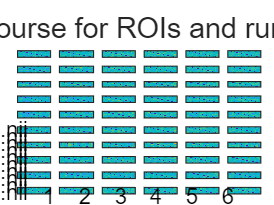

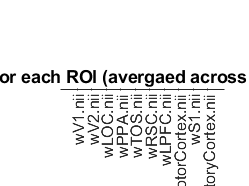

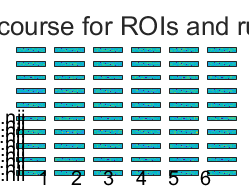

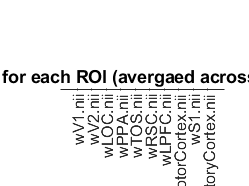


% get ISC from timecourses
cfg.partial_cor = false;
cfg.regressOutMean = true;
cfg.detrend = true;
cfg.correlation_type = 'Pearson';
d = neural_timecourse_intersub_cor(d, cfg);

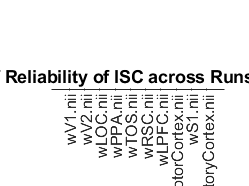

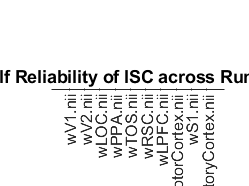


% get split-half reliability for ISC
d = splithalfReliabilityISC(d, cfg);

Compare ISC from drawings with timecourse ISC

 Start evaluating predictor RDMs
Predictor RDMs evaluated
10% of permutations of V1 bathroom is done
20% of permutations of V1 bathroom is done
30% of permutations of V1 bathroom is done
40% of permutations of V1 bathroom is done
50% of permutations of V1 bathroom is done
60% of permutations of V1 bathroom is done
70% of permutations of V1 bathroom is done
80% of permutations of V1 bathroom is done
90% of permutations of V1 bathroom is done
100% of permutations of V1 bathroom is done
Compare inter-subject RDM of V1 with partial correaltion of predictor RDMs - bathroom
 Start evaluating predictor RDMs
Predictor RDMs evaluated
10% of permutations of V1 kitchen is done
20% of permutations of V1 kitchen is done
30% of permutations of V1 kitchen is done
40% of permutations of V1 kitchen is done
50% of permutations of V1 kitchen is done
60% of permutations of V1 kitchen is done
70% of permutations of V1 kitchen is done
80% of permutations of V1 kitchen is done
90% of permutations of V1 kitch

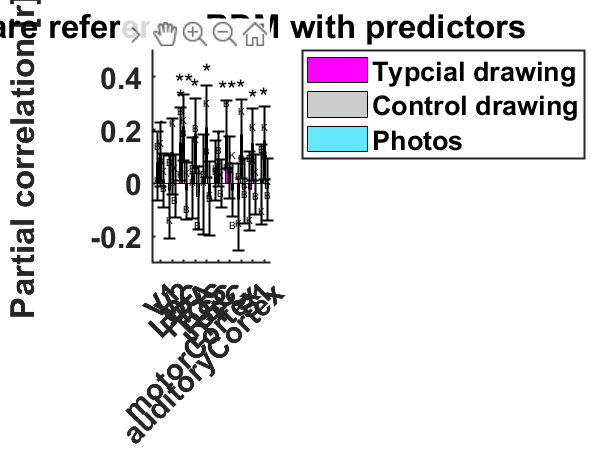

% preparation
cfg.partial_cor = true;
cfg.plot_rdm = false;
cfg.predictor_RDMs = {'typical_late', 'control_late', 'photos_late'};
cfg.RDM_to_partial_out = cfg.predictor_RDMs;
cfg.rois_of_interest = {'V1', 'V2', ...
    'LOC', 'PPA', 'TOS', 'RSC', 'LPFC',...
    'motorCortex', 'S1', 'auditoryCortex'};
cfg.dnns = {'vgg16_imagenet'};
cfg.plot_type = 'bar';
cfg.show_single_cate = true;
cfg.permutation_test = true;
cfg.n_permutations = 10000;
cfg.permutation_type = 'row_col_shuffle_ref';
cfg.ISC_type = 'timecourseRDM';
cfg.partial_correlation_type = 'Pearson';

d = compare_roi_RDMs_to_predictor_RDMs(d, cfg);

Get neural RDMs of single stimuli for each subject

% % % preparations
% % cfg.rois = {'wV1.nii', 'wV2.nii',...
% %     'wLOC.nii', 'wRSC.nii',...
% %     'wPPA.nii', 'wTOS.nii',...
% %  'wS1.nii', 'wauditoryCortex.nii'};
% % cfg.map = 't';
% % 
% % % run RDM based on simple correlations
% % d.simgpleRDMresults = Copy_of_SimpleRDM(cfg.subNums, cfg.nTrials, cfg.map, cfg.rois)

% % Get inter-subject similarity on single stimulus RDMs
% % % preparation
% % cfg.map = 't';
% % cfg.plotting = false;
% % 
% % % run neural ISC script
% % [d] = neural_intersub_cor(d, cfg)
% % 

Compare ISC from drawings with neural ISC

% % % preparation
% % cfg.partial_cor = 1;
% % cfg.plot_rdm = 0;
% % cfg.RDM_to_partial_out = {'Typical Images vgg16_imagenet Late', 'Control Images vgg16_imagenet Late'};
% % cfg.predictor_RDMs = {'typical_late', 'control_late'};
% % cfg.rois_of_interest = {'wV1', 'wLOC', 'wPPA', ...
% %     'wTOS', 'wRSC', 'wmotorCortex', 'wS1', 'wauditoryCortex'};
% % cfg.dnns = {'vgg16_imagenet'};
% % cfg.plot_type = 'bar';
% % cfg.show_single_cate = 1;
% % cfg.permutation_test = 1;
% % cfg.n_permutations = 1000;
% % cfg.permutation_type = 'row_col_shuffle_pred';
% % 
% % cfg.partial_correlation_type = 'pearson';
% % 
% % d = compare_roi_RDMs_to_predictor_RDMs(d, cfg);

End Message

% % finished!
% disp([ ...
%     newline, ...
%     '#########################', ...
%     newline, ...
%     '####### ALL DONE! #######', ...
%     newline, ...
%     '#########################', ...
%     newline ...
%     ]);